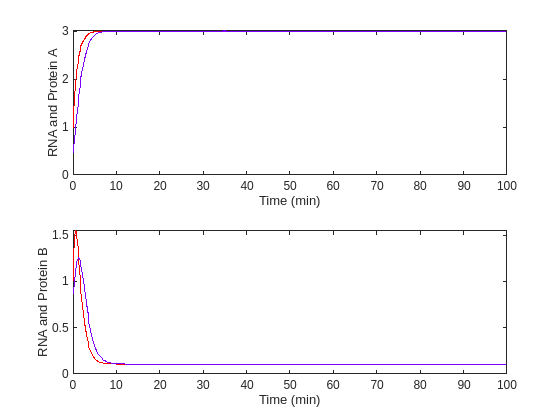


noisiness = 0.1;
noisiness2 = 0.1;

figure(); clf; 

numRuns = 100;
storage_A = zeros(1,numRuns);
storage_B = zeros(1,numRuns);
storage_Kba = zeros(1,numRuns);
storage_Kab = zeros(1,numRuns);

KbaVals = linspace(0, 2, numRuns);
          
for iRun = 1:numRuns
                    
    delta_ma = 1;
    gamma_pa = 1;
    delta_pa = 1;
    
    delta_mb = 1;
    gamma_pb = 1;
    delta_pb = 1;
    
    Kba = KbaVals(iRun); % Strength (IC50^-1) of inhibition of A by B
    Kaa = 0;
    gamma_ma =@(pb) 3./(1+abs(Kba*pb).^3);
    
    Kab = 1; % Strength (IC50) of inhibition of B by A
    Kbb = 0;
    gamma_mb =@(pa) 3./(1+abs(Kab*pa).^3);

    dmadt =@(ma,pa,mb,pb,t) +gamma_ma(pb) - delta_ma*ma;
    dpadt =@(ma,pa,mb,pb,t) +gamma_pa*ma - delta_pa*pa;
    
    dmbdt =@(ma,pa,mb,pb,t) +gamma_mb(pa) - delta_mb*mb;
    dpbdt =@(ma,pa,mb,pb,t) +gamma_pb*mb - delta_pb*pb;

    dxdt = @(t,x)[dmadt(x(1),x(2),x(3),x(4),t);
                  dpadt(x(1),x(2),x(3),x(4),t);
                  dmbdt(x(1),x(2),x(3),x(4),t);
                  dpbdt(x(1),x(2),x(3),x(4),t)];
    
    
    % initialCondition = 2*rand(4,1);
    initialConditions = [2;2;2;2];
    

    [T, X] = ode45(dxdt, [0.0,100], initialCondition);

    if iRun<10
        subplot(2,1,1);hold on; box on;
        plot(T,X(:,1),'-r'); % red for RNA
        plot(T,X(:,2),'-', 'color', [0.5 0 1]); % purple
        ylabel('RNA and Protein A')
        xlabel('Time (min)')

        subplot(2,1,2);hold on; box on;
        plot(T,X(:,3),'-r'); % red for RNA
        plot(T,X(:,4),'-', 'color', [0.5 0 1]); % purple
        ylabel('RNA and Protein B')
        xlabel('Time (min)')
    end

    storage_A(iRun) = X(end,2);
    storage_B(iRun) = X(end,4);
    storage_Kba(iRun) = Kba;
    storage_Kab(iRun) = Kab;
    
end

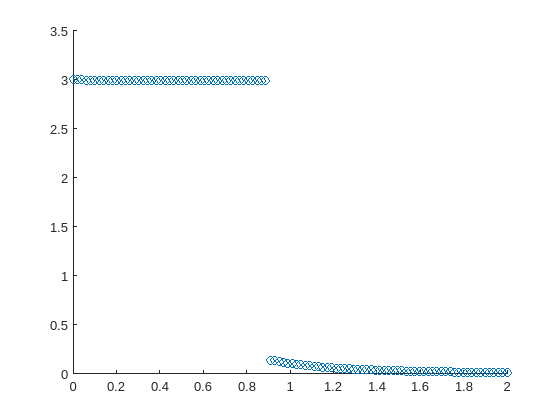


figure(); clf;
scatter(storage_Kba, storage_A);

% set(gca, "xscale", "log")

% figure(); clf; 
% subplot(1,2,1); hold on; box on;
% axis square
% histogram(storage_A, 50);
% xlabel('Amount of Protein A')
% 
% subplot(1,2,2); hold on; box on;
% axis square
% histogram(storage_B,50);
% xlabel('Amount of Protein B')
% 
% figure(); hold on; box on;
% axis square
% scatter(storage_A,storage_B,5);
% xlabel('Amount of Protein A')
% ylabel('Amount of Protein B')
